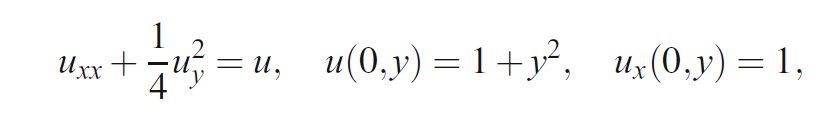

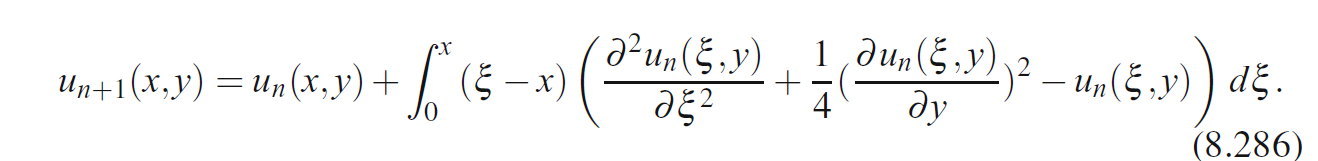

syms x y xi

Encontramos el valor de $u_0$


$$u_0 = 1 + y^2 +x $$


u0=1+y^2+x

$$u0 = y^{2}+x+1$$

Vamos a calcular lo que esta adentro de la integral

u0_xi=subs(u0,x,xi);
derivada1=diff(u0_xi,xi,2);
derivada2=(1/4)*(diff(u0_xi,y,1))^2;
adentro=derivada1 + derivada2 - u0_xi;
lambda_adentro=(xi-x)*adentro;
integral_n=int(lambda_adentro,xi,0,x);
u1=u0+integral_n;
expand(u1)

$$ans = \frac{x^{3}}{6}+\frac{x^{2}}{2}+x+y^{2}+1$$

u1_xi=subs(u1,x,xi);
derivada1=diff(u1_xi,xi,2);
derivada2=(1/4)*(diff(u1_xi,y,1))^2;
adentro=derivada1 + derivada2 - u1_xi;
lambda_adentro=(xi-x)*adentro;
integral_n=int(lambda_adentro,xi,0,x);
u2=u1+integral_n;
expand(u2)

$$ans = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+y^{2}+1$$

u2_xi=subs(u2,x,xi);
derivada1=diff(u2_xi,xi,2);
derivada2=(1/4)*(diff(u2_xi,y,1))^2;
adentro=derivada1 + derivada2 - u2_xi;
lambda_adentro=(xi-x)*adentro;
integral_n=int(lambda_adentro,xi,0,x);
u3=u2+integral_n;
expand(u3)

$$ans = \frac{x^{7}}{5040}+\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+y^{2}+1$$